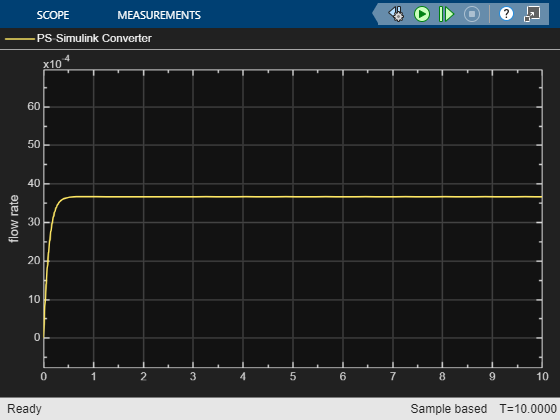

conditionName = 'unseen_restriction_001';

% Identify and run the currently open Simulink model.
modelName = bdroot(gcs);
simOutput = sim(modelName);


% Show what Simulink actually saved.
loggedNames = who(simOutput);
disp('Simulation output contains:');

Simulation output contains:


disp(loggedNames);

    {'flow_rate'}
    {'simlog'   }
    {'tout'     }




% Locate the Scope log under either possible name.
if any(strcmp(loggedNames, 'flow_log'))
    logName = 'flow_log';
elseif any(strcmp(loggedNames, 'flow_rate'))
    logName = 'flow_rate';
else
    error('No flow log found. Check that Scope logging is enabled.');
end

flowStruct = get(simOutput, logName);

time_s = flowStruct.time(:);
mass_flow_kg_s = squeeze(flowStruct.signals.values);
mass_flow_kg_s = mass_flow_kg_s(:);

flowTable = table( ...
    time_s, ...
    mass_flow_kg_s, ...
    'VariableNames', {'time_s', 'mass_flow_kg_s'});

outputFolder = ...
    'C:\Users\jhc125\OneDrive - Imperial College London\Global Challenge lab-IC-5CG52429X5';

outputPath = fullfile(outputFolder, [conditionName '.csv']);

writetable(flowTable, outputPath);

fprintf('Saved to:\n%s\n', outputPath);

Saved to:
C:\Users\jhc125\OneDrive - Imperial College London\Global Challenge lab-IC-5CG52429X5\unseen_restriction_001.csv
